clear all; 
Ea = 13.4E10; %elastic modulus ceramic
Em = 200E9; %[MPa]; %elastic modulus steel

rho_s = 7.8E3; %kg/m^3
rho_a = 7.7E3; %kg/m^3
U0 = 3.3; %micrometers
ha0 = 2E-3; %m


Fout = 1100; %Newton

A_a = (5E-3)^2;
A_c = (6E-3)^2;
A_T = (3E-3)^2;

h0 = 30; 
h1 = 80;
h_step = 0.1;
h = (h0:h_step:h1)*1E-3;
L1 = length(h);

La0 = 2;
La1 = 50;
La_step = 2; %each plate is 2mm
La = [La0:La_step:La1]*1E-3;
L2 = length(La);

alpha = zeros(L1,L2);
L_T = zeros(L1,L2);
ia = zeros(L1,L2);
iT = zeros(L1,L2);
S_out = zeros(L1,L2);
Isgood = zeros(L1,L2);
CT = zeros(L1,L2);
Cc = zeros(L1,L2);
Ca = zeros(L1,L2);
Ctot = zeros(L1,L2);
S_outgood = zeros(L1,L2);
S_outgoodbin = zeros(L1,L2);
for i=1:L1
    for j=1:L2
        %dimensions 
        alpha(i,j) = atan(h(i)/La(j));
        L_T(i,j) = La(j)/(2*cos( alpha(i,j) ) );
        
        %transmission ratio's
        ia(i,j) = La(j)/h(i); 
        CT(i,j) = Em * A_T / L_T(i,j);
        Cc(i,j) = Em * A_c / h(i);
        Ca(i,j) = Ea * A_a / La(j);
        Ctot(i,j) = Cc(i,j) + 0.5*CT(i,j)*iT(i,j)^2 + Ca(i,j)*ia(i,j)^2;
        Csys(i,j) = ((Cc(i,j))^-1 + (2*CT(i,j)/(iT(i,j)^2))^-1)^-1;
        iT(i,j) = sin(alpha(i,j));
        iagoodbin(i,j) = (ia(i,j) < 1);
        
        %stiffnesses
       
        
        F0(i,j) = Fout*ia(i,j);
        %output stroke
        umax(i,j) = ((La(j)-La0*1E-3)/(La0*1E-3))*U0;
        xp(i,j) = (umax(i,j)-F0(i,j)/Ca(i,j))/(1+(Csys(i,j)/Ca(i,j)));
        S_out(i,j) = xp(i,j)*ia(i,j);
        Isgoodsurf(i,j) = (ia(i,j) < 1);
        S_outgoodsurf(i,j) = Isgoodsurf(i,j)*Isgoodsurf(i,j);
        Isgood(i,j) = (S_out(i,j) >= 10) && (S_out(i,j) <= 11);
        S_outgood(i,j) = Isgood(i,j)*S_out(i,j);
     
        iagood(i,j) =  ia(i,j)*Isgood(i,j);
        F0good(i,j) = F0(i,j)*Isgood(i,j);
        mnz(:,j) = mean(nonzeros(S_outgood(:,j)));
        defiation(:,j) = max(S_outgood(:,j))-mnz(:,j);
        
        
        massa(i,j) = rho_a*A_a*La(j);
        massc(i,j) = rho_s*A_c*h(i);
        masst(i,j) = 4*rho_s*A_T*(L_T(i,j));
        masstotal(i,j) = massa(i,j)+massc(i,j)+masst(i,j);
        
        sc(i,j) = Ctot(i,j)/masstotal(i,j);
        
        alphagood(i,j) = Isgood(i,j)*alpha(i,j);
        
    end
end

S_outgood(S_outgood==0) = NaN;
F0(F0==0) = NaN;
   alphagood(alphagood ==0) = NaN;

for ii = 1:4
   
minalpha(ii) = (min(alphagood(:,(ii+5))));
beta(ii) = 0.5*pi-minalpha(ii);
Fres(ii) = cos(beta(ii))*Fout;
at(ii) = Fres(ii)/(720*1E6);
wt(ii) = sqrt(at(ii))*1E3;
end

delta = 1000*h/(Em*A_T);

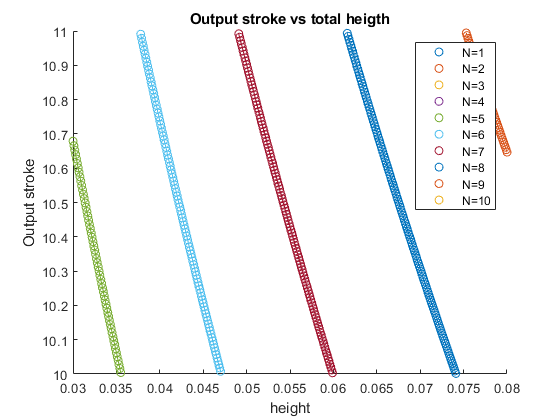

figure()
scatter(h, S_outgood)
line(h,S_outgood);
title('Output stroke vs total heigth')
xlabel('height')
ylabel('Output stroke')
legend( 'N=1', 'N=2', 'N=3', 'N=4', 'N=5', 'N=6', 'N=7', 'N=8', 'N=9', 'N=10') 

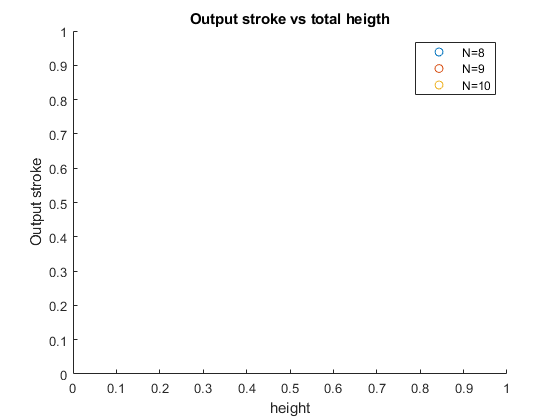




figure()
scatter(h, S_outgood(:,8:10))
line(h,S_outgood(:,8:10));
title('Output stroke vs total heigth')
xlabel('height')
ylabel('Output stroke')
legend( 'N=8', 'N=9', 'N=10')

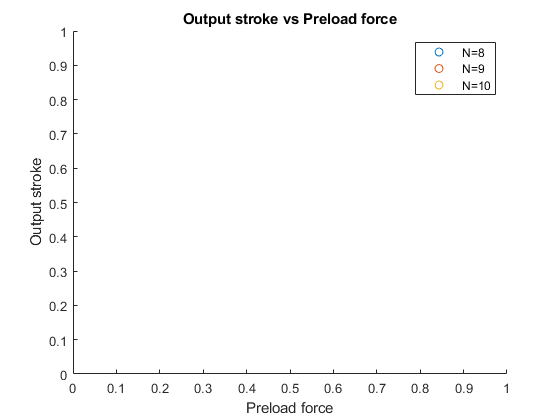




figure()
scatter(F0(:,8:10), S_outgood(:,8:10))
line(F0(:,8:10),S_outgood(:,8:10))
title('Output stroke vs Preload force')
xlabel('Preload force')
ylabel('Output stroke')
legend( 'N=8', 'N=9', 'N=10')

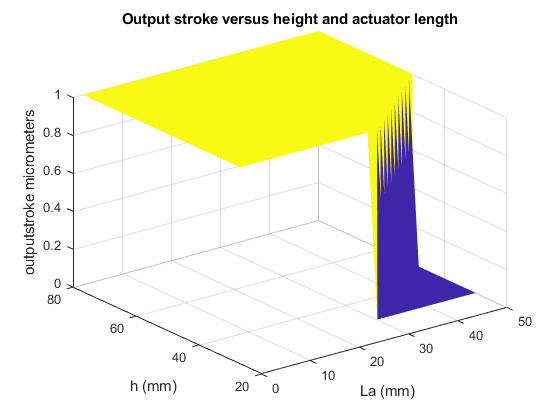











[X,Y] = meshgrid(La0:La_step:La1,h0:h_step:h1);

figure 
clf
s1 = surf(X,Y,S_outgoodsurf);
s1.EdgeColor = 'none';

title('Output stroke versus height and actuator length')
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('outputstroke micrometers')

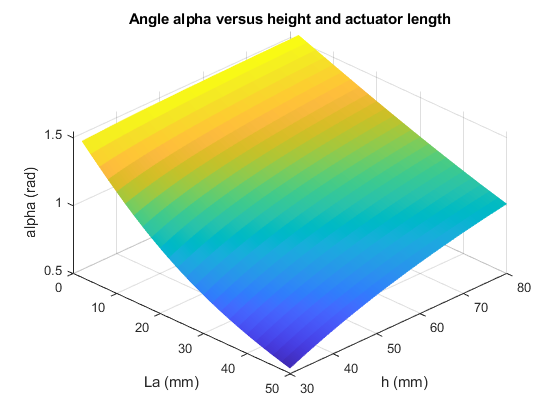

%saveas(gcf,'ssa9/outputstroke.png')


figure 
clf
s1 = surf(X,Y,alpha);
s1.EdgeColor = 'none';

title("Angle alpha versus height and actuator length")
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('alpha (rad)')
view([45 45])

% saveas(gcf,'ssa9/alpha.png')

f = figure 

f =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


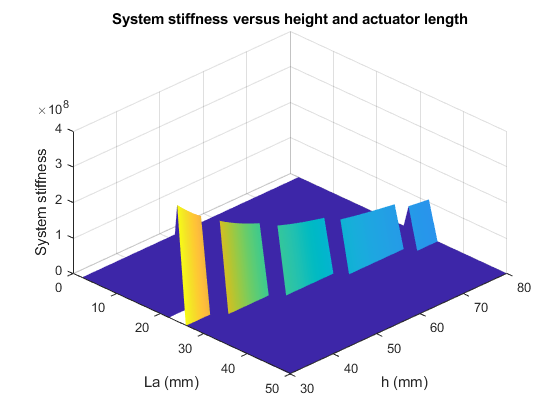

clf
s1 = surf(X,Y,Ctot.*Isgood);
s1.EdgeColor = 'none';

title('System stiffness versus height and actuator length')
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('System stiffness')
view([45 45])

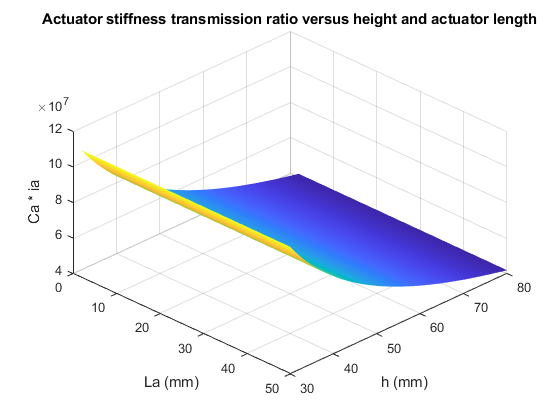

% saveas(gcf,'ssa9/systemstiff.png')

figure 
clf
s1 = surf(X,Y,Ca.*ia);
s1.EdgeColor = 'none';

title("Actuator stiffness transmission ratio versus height and actuator length")
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('Ca * ia')
view([45 45])

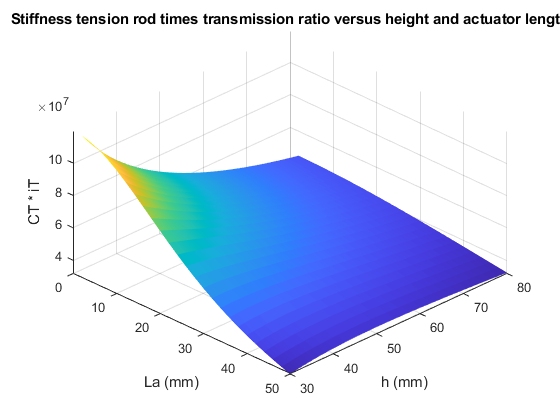

% saveas(gcf,'ssa9/actuatorstiff.png')

figure 
clf
s1 = surf(X,Y,CT.*iT);
s1.EdgeColor = 'none';

title("Stiffness tension rod times transmission ratio versus height and actuator length")
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('CT * iT')
view([45 45])

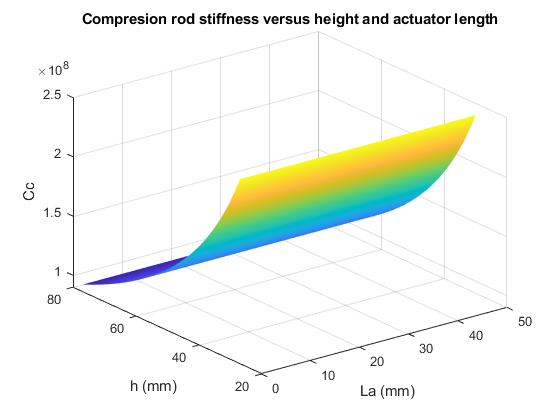

% saveas(gcf,'ssa9/tensionstiff.png')

figure 
clf
s1 = surf(X,Y,Cc);
s1.EdgeColor = 'none';

title('Compresion rod stiffness versus height and actuator length')
xlabel("La (mm)")
ylabel("h (mm)")
zlabel('Cc')

% saveas(gcf,'ssa9/compresionstiff.png')
